Set up point loads & their location on the bridge

% Customize bridge length, first load location, and point loads
bridge_length = 1250;
ultimate_compressive_m = 6;
ultimate_tensile_m = 30;
ultimate_tau_glue = 2;
ultimate_tau_xy = 4;
points = [0 176 340 516 680 856]';
loads = [90 90  66.6 66.6 66.6 66.6]';
first_load_locations = [1 : bridge_length - 856];
number_of_components = 6;
bridge_height = 76.27;
glue_height = 75;
b_glue = 80;
E = 4000;
mu = 0.2;


Set up cross-sectional dimensions & ultimate strength of bridge

% Customize dimensions

bases = ones(number_of_components, bridge_length);
for x = 1 : bridge_length
bases(:,(x)) = [80; 1.27; 1.27; 40; 40; 100]';
end

heights = ones(number_of_components, bridge_length);
for x = 1 : bridge_length
heights(:,(x)) = [1.27; 73.73; 73.73; 1.27; 1.27; 1.27]';
end

heights_from_bottom = ones(number_of_components, bridge_length);
for x = 1 : bridge_length
heights_from_bottom(:,(x)) = [0; 1.27; 1.27; 73.73; 73.73; 75]';
end

% Calculate Total Matboard Needed
areas_calculated = [80; 73.73; 73.73; 80; 100];
areas_calculated = areas_calculated .* bridge_length;
total_matboard_needed = (sum(areas_calculated) + 6 * (230 * 25))/ 10^6;
volume_matboard_needed = sum(areas_calculated) * 1.27 /10^9;
mass = 714.946 * volume_matboard_needed;
newtons = mass * 9.81;


thickness_flanges = 1.27; %assume same thickness for all flanges
thickness_webs = 1.27; %assume same thickness for all webs

width_between_webs = 80; %end to end
width_web = 1.27;
width_top_flange = 100;
height_to_top_flange = 75;
height_bottom_flange = 1.27;
a = 400;


Calculate Maximum Capacities Along Bridge

information = ones(8, bridge_length);
for n = 1 : bridge_length
[y_bar, y_top, y_bottom, I_total, Q_xy, b_centroidal, Q_glue, dimensions] = calculate_information(bases, heights, heights_from_bottom, number_of_components, bridge_height, n, glue_height);
information(:, n) = [y_bar, y_top, y_bottom, I_total, Q_xy, b_centroidal, Q_glue, b_glue];
end

Plot shear failure diagram

Plot Shear Forces

max_shears = zeros(1, length(first_load_locations));
shear_envelope = zeros(1, bridge_length);
max_shear_train_location = 0;
min_shear_train_location = 0;
subplot(2, 3, 1);
for n = 1 : length(first_load_locations)
    first_load_location = first_load_locations(n);
    [shear_forces, bending_moments, diagram_points, min_shear, max_shear, min_moment, max_moment] = calculate(bridge_length, first_load_location, points, loads);
    % Customize axis limits
    shear_forces(end - bridge_length - 3) = shear_forces(end - bridge_length - 1);
    plot(shear_forces(:,2),shear_forces(:,1), "k")
    hold on
    max_shears(:, n) = max_shear(1);
    min_shears(:, n) = min_shear(1);
    for k = 1 : bridge_length
         if abs(shear_envelope(k)) < abs(shear_forces(k, 1))
            shear_envelope(k) = shear_forces(k, 1);
         end
         if max(shear_envelope) == max(shear_forces(:, 1))
             max_shear_train_location = n;
         end
         if min(shear_envelope) == min(shear_forces(:, 1))
             min_shear_train_location = n;
         end
    end 
yline(0)
axis([-0.02 1.27 -700 700])
title("Shear Failure Diagram")
xlabel("Distance Across Bridge [m]")
ylabel("Shear Force [N]")
end


Calculate Maximum Value of Applied Tau_xy Along Bridge

max_shear_value = max(max_shears);
min_shear_value = -max(max_shears);
extreme_shears = [abs(min_shear_value) abs(max_shear_value)];

taus_xy = (max(extreme_shears) .* information(5,:)) ./ (information(4,:) .* information(6,:));
fos_taus_xy = ultimate_tau_xy ./ taus_xy;
min_fos_tau = min(fos_taus_xy);

Calculate Matboard Capacities Along Bridge

top_fails = fos_taus_xy .* max_shear_value;
bottom_fails = fos_taus_xy .* min_shear_value;

top_fails_legend = plot((1:bridge_length)/1000, top_fails, "r");
bottom_fails_legend = plot((1:bridge_length)/1000, bottom_fails, "r");
capacity_legend = [top_fails_legend];
legend(capacity_legend, "Matboard Shear Failure")
hold off

Plot Glue Shear Failure Diagram 

Calculate Maximum Value of Applied Tau_glue Along Bridge

taus_glue = (max(extreme_shears) .* information(7,:)) ./ (information(4,:) .* information(8,:));
fos_taus_glue = ultimate_tau_glue ./ taus_glue;
min_fos_glue = min(fos_taus_glue);


Calculate Glue Capacities Along Bridge

top_glue_fails = fos_taus_glue .* max_shear_value;
bottom_glue_fails = fos_taus_glue .* min_shear_value;
subplot(2, 3, 2);
h = plot((1:bridge_length)/1000, top_glue_fails, "r");
hold on
glue = plot((1:bridge_length)/1000, bottom_glue_fails, "r");

Plot Shear Forces

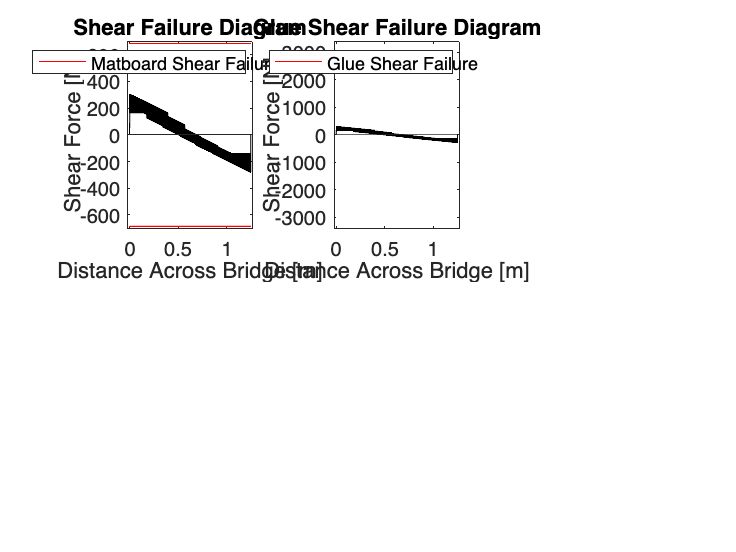

max_shears = zeros(1, 3);
for n = 1 : length(first_load_locations)
    first_load_location = first_load_locations(n);
    [shear_forces, bending_moments, diagram_points, min_shear, max_shear, min_moment, max_moment] = calculate(bridge_length, first_load_location, points, loads);
    % Customize axis limits
    shear_forces(end - bridge_length - 3) = shear_forces(end - bridge_length - 1);
    plot(shear_forces(:,2),shear_forces(:,1), "k")
    max_shears(:, n) = max_shear(1);
min_shears(:, n) = min_shear(1);
end 
yline(0)
axis([-0.02 1.27 -3400 3400])
title("Glue Shear Failure Diagram")
xlabel("Distance Across Bridge [m]")
ylabel("Shear Force [N]")
legend("Glue Shear Failure")
hold off

Plot bending moment diagram

Plot Bending Moments

max_moments = zeros(1,length(first_load_locations));
moment_envelope = zeros(1, bridge_length);
subplot(2, 3, 4);
max_moment_train_location = 0;
for n = 1 : length(first_load_locations)
    first_load_location = first_load_locations(n);
    [shear_forces, bending_moments, diagram_points, min_shear, max_shear, min_moment, max_moment] = calculate(bridge_length, first_load_location, points, loads);
    % Customize axis limits
    plot(bending_moments(:, 2), bending_moments(:, 1), "k")
    bending_values = zeros(2, length(bending_moments))';
    bending_values(:, 1) = bending_moments(:, 2) * 1000;
    bending_values(:, 2) = bending_moments(:, 1);
    full_bending_moments = interp1(bending_values((1:length(bending_values) - 1), 1), bending_values((1:length(bending_values) - 1), 2), (1:bridge_length));
    hold on
    max_moments(:,n) = max_moment(1);
    for k = 1 : bridge_length
         if moment_envelope(k) < full_bending_moments(k)
            moment_envelope(k) = full_bending_moments(k);
         end
         if max(moment_envelope) == max(full_bending_moments)
            max_moment_train_location = n;
         end
    end 
end
yline(0)
axis([-0.02 1.27 -100 375])
title("Bending Moment Diagram")
xlabel("Distance Across Bridge [m]")
ylabel("Bending Moment [Nm]")
set(gca, "yDir", "reverse")

Calculate Maximum Value of Applied Tension & Compression  Along Bridge

max_shear_location = find(shear_envelope == max(shear_envelope));
min_shear_location = find(shear_envelope == min(shear_envelope));
max_moment_location = find(moment_envelope == max(moment_envelope));
smallest_shear_force = min(abs(shear_envelope(2:end-2)));
splice_location = find(abs(shear_envelope) == smallest_shear_force);
maximum_shear_force = max(shear_envelope);
minimum_shear_force = min(shear_envelope);
maximum_bending_moment = max(moment_envelope);
greatest_moment_value = max(max_moments);
greatest_moment_value = greatest_moment_value * 1000;
max_compressions = (information(2,:) .* greatest_moment_value) ./ information(4);
max_tensions = (information(3,:) .* greatest_moment_value) ./ information(4);


Calculate FOS Against Tension & Compression Along Bridge

fos_compressions = ultimate_compressive_m./max_compressions;
min_fos_compression = min(fos_compressions);
fos_tensions = ultimate_tensile_m./max_tensions;
min_fos_tension = min(fos_tensions);

Calculate Tension & Compression Capacities Along Bridge

tension_fails = fos_tensions .* (greatest_moment_value/1000);
compression_fails = fos_compressions .* (greatest_moment_value/1000);


Plot Tension & Compression Failure Loads

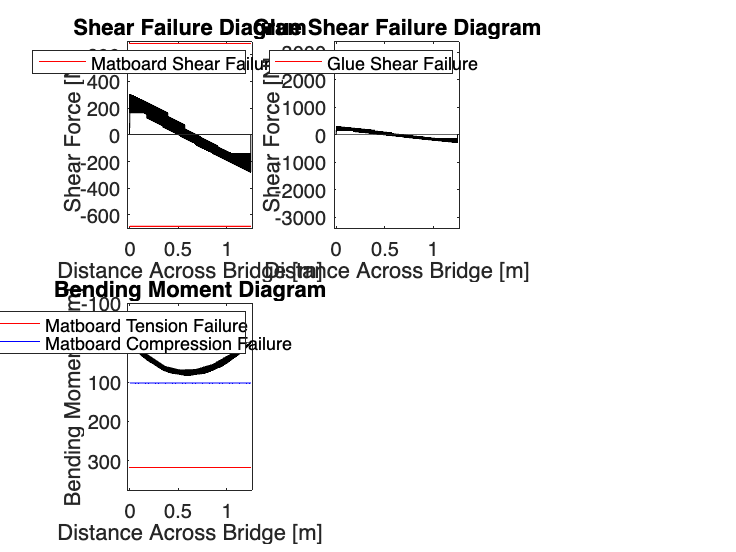

tension_failure_legend = plot((1:bridge_length)/1000, tension_fails, "r");
compression_failure_legend = plot((1:bridge_length)/1000, compression_fails, "b");
bending_moment_legend = [tension_failure_legend, compression_failure_legend];

legend(bending_moment_legend, "Matboard Tension Failure", "Matboard Compression Failure")
hold off

Plot Envelopes

% plot((1:bridge_length)/1000,shear_envelope)
% hold on
% yline(0)
% title("Shear Force Envelope")
% ylabel("Shear Force [N]")
% xlabel("Distance Across Bridge [m]")
% axis([-0.020 1.220 -300 300])
% hold off
% 
% plot((1:bridge_length)/1000,moment_envelope)
% hold on
% yline(0)
% title("Bending Moment Envelope")
% ylabel("Bending Moment [Nm]")
% xlabel("Distance Across Bridge [m]")
% set(gca, "yDir", "reverse")
% hold off

Thin Plate Buckling

%Case 1
b = width_between_webs - 2.*width_web; % *2 since two webs
Tcr1 = (4 .* pi.^2 .* E) ./ (12 .* (1-mu.^2)) .* (thickness_flanges * 2 / b).^2;
fos_buck1 = Tcr1 ./ max_compressions;
min_fos_buck1 = min(fos_buck1);


%Case 2
b = (width_top_flange - width_between_webs)./2 + width_web ./ 2; %width of end to web + 1/2 width of web
Tcr2 = (0.425 .* pi.^2 .* E) ./ (12 .* (1-mu.^2)) .* (thickness_flanges * 2 / b).^2;
fos_buck2 = Tcr2 ./ max_compressions;
min_fos_buck2 = min(fos_buck2);


%Case 3
b = height_to_top_flange - y_bar;
Tcr3 = (6 .* pi.^2 .* E) ./ (12 .* (1-mu.^2)) .* (thickness_webs / b).^2;
fos_buck3 = Tcr3 ./ max_compressions;
min_fos_buck3 = min(fos_buck3);


%Shear Buckling
b = height_to_top_flange - height_bottom_flange; %height from bottom to top flange - height of bottom flange
Tcr4 = (5 .* pi.^2 .* E) ./ (12 .* (1-mu.^2)) .* ((thickness_webs / b).^2 + (thickness_webs ./ a).^2);
fos_buck_shear = Tcr4 ./ taus_xy;
min_fos_buck_shear = min(fos_buck_shear);

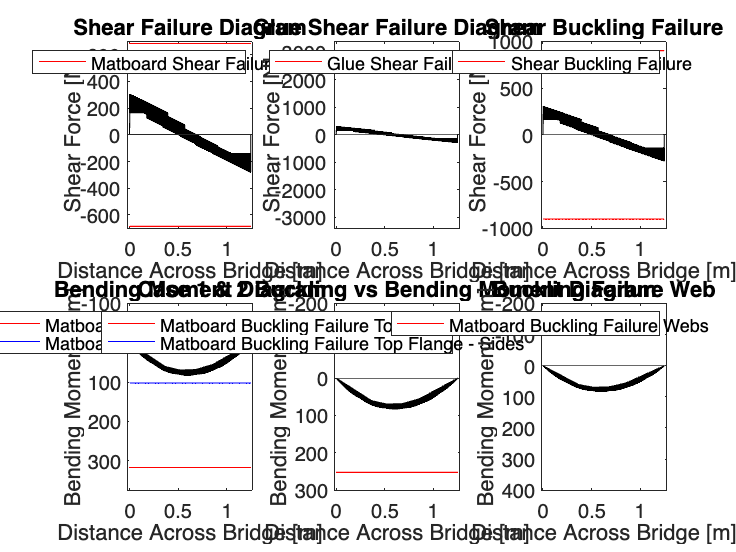

buckling1_failure = fos_buck1 .* (greatest_moment_value/1000); %divide by thousand for mm -> m
buckling2_failure = fos_buck2 .* (greatest_moment_value/1000);
buckling3_failure = fos_buck3 .* (greatest_moment_value/1000);
shear_buckling_failure = fos_buck_shear .* (max_shear_value);

%Buckling Case 1, 2 (top flange middle and edges)
subplot(2, 3, 5);
for n = 1 : length(first_load_locations)
    first_load_location = first_load_locations(n);
    [shear_forces, bending_moments, diagram_points, min_shear, max_shear, min_moment, max_moment] = calculate(bridge_length, first_load_location, points, loads);
    % Customize axis limits
    plot(bending_moments(:, 2), bending_moments(:, 1), "k")
    hold on
    max_moments(:,n) = max_moment(1);
end
yline(0)
axis([-0.02 1.27 -200 300])
label1 = plot((1:bridge_length)/1000, buckling1_failure, "r");
label2 = plot((1:bridge_length)/1000, buckling2_failure, "b");
legend_labels = [label1, label2];
legend(legend_labels, "Matboard Buckling Failure Top Flange - Mid", "Matboard Buckling Failure Top Flange - Sides")
title("Case 1 & 2 Buckling vs Bending Moment Diagram")    
xlabel("Distance Across Bridge [m]")
ylabel("Bending Moment [Nm]")
set(gca, "yDir", "reverse")
hold off

subplot(2, 3, 6);
for n = 1 : length(first_load_locations)
    first_load_location = first_load_locations(n);
    [shear_forces, bending_moments, diagram_points, min_shear, max_shear, min_moment, max_moment] = calculate(bridge_length, first_load_location, points, loads);
    % Customize axis limits
    plot(bending_moments(:, 2), bending_moments(:, 1), "k")
    hold on
    max_moments(:,n) = max_moment(1);
end
yline(0)
axis([-0.02 1.27 -200 400])
label1 = plot((1:bridge_length)/1000, buckling3_failure, "r");
legend_labels = [label1];
legend(legend_labels, "Matboard Buckling Failure Webs")
title("Buckling Failure Web")
xlabel("Distance Across Bridge [m]")
ylabel("Bending Moment [Nm]")
set(gca, "yDir", "reverse")
hold off

subplot(2, 3, 3);
for n = 1 : length(first_load_locations)
    first_load_location = first_load_locations(n);
    [shear_forces, bending_moments, diagram_points, min_shear, max_shear, min_moment, max_moment] = calculate(bridge_length, first_load_location, points, loads);
    % Customize axis limits
    shear_forces(end - bridge_length - 3) = shear_forces(end - bridge_length - 1);
    plot(shear_forces(:,2),shear_forces(:,1), "k")
    hold on
    max_shears(:, n) = max_shear(1);
    min_shears(:, n) = min_shear(1);
end 
yline(0)
axis([-0.02 1.27 -1000 1000])
label1 = plot((1:bridge_length)/1000, shear_buckling_failure, "r");
label2 = plot((1:bridge_length)/1000, shear_buckling_failure .* -1, "r");
legend_labels = [label1];
legend(legend_labels, "Shear Buckling Failure")
title("Shear Buckling Failure")
xlabel("Distance Across Bridge [m]")
ylabel("Shear Force [N]")
hold off

% loads = [repelem(1, 4), repelem(1 * freight_to_locomotive, 2)]'

load_ratios = [1.35, 1.35, 1, 1, 1, 1];
loads = load_ratios';

max_loading_moments = zeros(1,length(first_load_locations));
max_loading_shears = zeros(1, length(first_load_locations));

for n = 1 : length(first_load_locations)
    first_load_location = first_load_locations(n);
    [shear_forces, bending_moments, diagram_points, min_shear, max_shear, min_moment, max_moment] = calculate(bridge_length, first_load_location, points, loads);
    max_loading_moments(:,n) = max_moment(1);
    max_loading_shears(:, n) = max_shear(1);
    
end
greatest_loading_moment_value = max(max_loading_moments) * 1000;
greatest_loading_shear_value = max(max_loading_shears);

max_comp_load = (ultimate_compressive_m .* I_total) / (y_top * greatest_loading_moment_value);
max_tens_load = (ultimate_tensile_m .* I_total) / (y_bottom * greatest_loading_moment_value);
max_shear_load = (ultimate_tau_xy * I_total * b_centroidal) / (Q_xy * greatest_loading_shear_value);
max_shear_glue = (ultimate_tau_glue * I_total * b_glue) / (Q_glue * greatest_loading_shear_value);
max_buckling1_load = (Tcr1 .* I_total) / (y_top * greatest_loading_moment_value);
max_buckling2_load = (Tcr2 .* I_total) / (y_top * greatest_loading_moment_value);
max_buckling3_load = (Tcr3 .* I_total) / (y_top * greatest_loading_moment_value);
max_buckling4_load = (Tcr4 * I_total * b_centroidal) / (Q_xy * greatest_loading_shear_value);
max_loads = [max_comp_load max_tens_load max_shear_load max_shear_glue max_buckling1_load max_buckling2_load max_buckling3_load max_buckling4_load];
max_load = min(max_loads);
max_total_loads = max_load .* loads;
max_total_load = sum(max_total_loads);
ratio = max_total_load/newtons;

Display Information

[y_bar, y_top, y_bottom, I_total, Q_xy, b_centroidal, Q_glue, dimensions] = calculate_information(bases, heights, heights_from_bottom, number_of_components, bridge_height, n, glue_height);
disp(["BRIDGE INFORMATION"])

BRIDGE INFORMATION


disp(["Total Matboard Available [m^2]: ", total_matboard_available])

    "Total Matboard Available [m^2]: "    "0.82601"



disp(["Total Matboard Needed [m^2]: ", total_matboard_needed])

    "Total Matboard Needed [m^2]: "    "0.54383"



disp(["Mass [kg]: ", mass])

    "Mass [kg]: "    "0.46246"



disp(["Bridge Dimensions (Bases, Heights, Heights from Bottom)"])

Bridge Dimensions (Bases, Heights, Heights from Bottom)


disp([dimensions])

   80.0000    1.2700         0
    1.2700   73.7300    1.2700
    1.2700   73.7300    1.2700
   40.0000    1.2700   73.7300
   40.0000    1.2700   73.7300
  100.0000    1.2700   75.0000



disp([""])
disp(["ULTIMATE CAPACITIES [MPa]"])

ULTIMATE CAPACITIES [MPa]


disp(["Flexural Compression: ", ultimate_compressive_m])

    "Flexural Compression: "    "6"



disp(["Flexural Tension: ", ultimate_tensile_m])

    "Flexural Tension: "    "30"



disp(["Centroidal Shear: ", ultimate_tau_xy])

    "Centroidal Shear: "    "4"



disp(["Glue Shear : ", ultimate_tau_glue])

    "Glue Shear : "    "2"



disp(["Case 1 Buckling: ", Tcr1])

    "Case 1 Buckling: "    "14.7394"



disp(["Case 2 Buckling: ", Tcr2])

    "Case 2 Buckling: "    "83.0785"



disp(["Case 3 Buckling: ", Tcr3])

    "Case 3 Buckling: "    "42.5712"



disp(["Shear Buckling: ", Tcr4])

    "Shear Buckling: "    "5.2566"



disp([""])
disp(["MINIMUM FOS"])

MINIMUM FOS


disp(["Shear: ", min_fos_tau])

    "Shear: "    "2.2455"



disp(["Shear Glue: ", min_fos_glue])

    "Shear Glue: "    "72.0436"



disp(["Flexural Compression: ", min_fos_compression])

    "Flexural Compression: "    "1.2387"



disp(["Flexural Tension: ", min_fos_tension])

    "Flexural Tension: "    "3.8382"



disp(["Case 1 Buckling: ", min_fos_buck1])

    "Case 1 Buckling: "    "3.043"



disp(["Case 2 Buckling: ", min_fos_buck2])

    "Case 2 Buckling: "    "17.1519"



disp(["Case 3 Buckling: ", min_fos_buck3])

    "Case 3 Buckling: "    "8.789"



disp(["Shear Buckling: ", min_fos_buck_shear])

    "Shear Buckling: "    "2.9509"



disp([""])
disp(["MAXIMUM POSSIBLE LOADS [N]"])

MAXIMUM POSSIBLE LOADS [N]


disp(["Compressive: ", max_comp_load])

    "Compressive: "    "82.5315"



disp(["Tensile: ", max_tens_load])

    "Tensile: "    "255.7232"



disp(["Shear: ", max_shear_load])

    "Shear: "    "149.6318"



disp(["Shear Glue: ", max_shear_glue])

    "Shear Glue: "    "4800.7276"



disp(["Case 1 Buckling: ", max_buckling1_load])

    "Case 1 Buckling: "    "202.744"



disp(["Case 2 Buckling: ", max_buckling2_load])

    "Case 2 Buckling: "    "1142.7652"



disp(["Case 3 Buckling: ", max_buckling3_load])

    "Case 3 Buckling: "    "585.5767"



disp(["Case 4 Buckling: ", max_buckling4_load])

    "Case 4 Buckling: "    "196.6393"



disp(["Point Load: ", max_load])

    "Point Load: "    "82.5315"



disp(["Total Train Load: ", max_total_load])

    "Total Train Load: "    "552.9609"



disp([""])
disp(["EXTRA INFORMATION"])

EXTRA INFORMATION


disp(["Bridge Weight to Load Capacity Ratio [N]: ", ratio])

    "Bridge Weight to Load Capacity Ratio [N]: "    "121.8859"



disp(["Train Location for Maximum Upwards Shear Force [mm from end]: ", max_shear_train_location])

    "Train Location for Maximum Upwards Shear Force [mm from end]: "    "3"



disp(["Train Location for Maximum Downwards Shear Force [mm from end]: ", min_shear_train_location])

    "Train Location for Maximum Downwards Shear Force [mm from end]: "    "392"



disp(["Maximum Upwards Shear Force [N]: ", maximum_shear_force])

    "Maximum Upwards Shear Force [N]: "    "305.2109"



disp(["Maximum Downwards Shear Force [N]: ", minimum_shear_force])

    "Maximum Downwards Shear Force [N]: "    "-280.1088"



disp(["Train Location for Maximum Bending Moment [mm from end]: ", max_moment_train_location])

    "Train Location for Maximum Bending Moment [mm from end]: "    "259"



disp(["Maximum Bending Moment [N*m]: ", maximum_bending_moment])

    "Maximum Bending Moment [N*m]: "    "82.6991"



Calculate Applied Forces 

function [shear_forces, bending_moments, diagram_points, min_shear, max_shear, min_moment, max_moment] = calculate(bridge_length, first_load_location, points, loads)
pointloads = zeros(length(points), 2);
pointloads(:, 1) = pointloads(:, 1) + loads;
pointloads(:, 2) = pointloads(:, 2) + (points + first_load_location);
total_load = sum(pointloads(:, 1));
moments = pointloads(:, 1) .* pointloads(:, 2);
reactionB = sum(moments)/bridge_length;
reactionA = total_load - reactionB;

Create array of all bridge loads including reaction forces and considering direction

diagram_points = zeros(length(pointloads) + 2, 1);
diagram_points(end) = bridge_length;
diagram_points(2 : end - 1) = pointloads(:, 2);

pointloads(:, 1) = pointloads(:, 1) .* -1;
bridgeloads = zeros(length(pointloads) + 2, 1);
bridgeloads(1) = reactionA;
bridgeloads(end) = reactionB;
bridgeloads(2 : end - 1) = pointloads(:, 1);

shear_loads = zeros(length(bridgeloads), 2);
shear_loads(:, 1) = shear_loads(:, 1) + bridgeloads;
shear_loads(:, 2) = shear_loads(:, 2) + diagram_points;

Calculate shear force diagram 

shear_forces = zeros(bridge_length + 1, 2);

shear_forces(1) = 0;
for idx = 2 : length(shear_forces)
    applied_forces = shear_loads(shear_loads(:, 2) <= idx);
    shear_forces(idx) = sum(applied_forces);
    shear_forces(idx + length(shear_forces)) = idx/1000;
end

simple_shear = zeros(length(diagram_points), 2);
for idx = 1:length(diagram_points)
    force_sum = 0;
    for point = 1 : idx
        force_sum = force_sum + shear_loads(point);
    end
    simple_shear(idx) = force_sum;
    simple_shear(idx + length(simple_shear)) = diagram_points(idx)/1000;
end
simple_shear_forces = simple_shear(1 : end - 1, 1);
simple_shear_points = simple_shear(2 : end, 2);

shear_forces(end - bridge_length - 3) = shear_forces(end - bridge_length - 1);


min_shear = min(shear_forces);
max_shear = max(shear_forces);

Calculate bending moment diagram 

bending_moments = zeros(length(diagram_points), 2);
diagram_points = diagram_points ./ 1000;
bending_moments(:, 2) = diagram_points;
bending_moments(1) = 0;
for idx = 2 : length(diagram_points)
    reference = diagram_points(idx);
    loads = simple_shear_forces(simple_shear_points <= reference);
    points = simple_shear_points(simple_shear_points <= reference);
    calc_points = zeros(length(points), 1);
    calc_points(1) = points(1);
    calc_points(2:end) = points(2:end) - points(1:end-1);
    moments = loads .* calc_points;
    bending_moments(idx) = sum(moments);
end
min_moment = min(bending_moments(:,1));
max_moment = max(bending_moments(:,1));
end

Calculate capacities along bridge

function [y_bar, y_top, y_bottom, I_total, Q_xy, b_centroidal, Q_glue, dimensions] = calculate_information(bases, heights, heights_from_bottom, number_of_components, bridge_height, n, glue_height)

% Customize dimensions, bridge height, ultimate stresses
dimensions = ones(number_of_components, 3);
dimensions(:, 1) = bases(:,n);
dimensions(:, 2) = heights(:,n);
dimensions(:, 3) = heights_from_bottom(:, n);


Calculate y-bar

numerators = dimensions(:, 1) .* dimensions(:, 2) .* (dimensions(:, 3) + (dimensions(:,2)./2));
denominators = dimensions(:, 1) .* dimensions(:, 2);
numerator = sum(numerators);
denominator = sum(denominators);
y_bar = numerator/denominator;

Calculate maximum y-bottom and maximum y-top

y_top = bridge_height - y_bar;
y_bottom = y_bar;

Calculate I-total

I_values = dimensions(:,1) .* (dimensions(:,2).^3) .* 1/12;
y_values = ((dimensions(:, 3) + (dimensions(:,2)./2)) - y_bar).^2;
deviation_values = denominators .* y_values;
I_total = sum(I_values) + sum(deviation_values);

Calculate Q at Centroidal Axis

Use the distance between Centroidal Axis & bridge bottom

centroids = dimensions(:,3) + (dimensions(:,2)/2);
top_heights = dimensions(:, 2) + dimensions(:, 3);
bottom_heights = dimensions(:,3);
full_areas = dimensions(:, 1) .* dimensions (:,2);
full_areas(top_heights >= y_bar) = 0;
partial_heights = y_bar - bottom_heights;
partial_heights(partial_heights < 0) = 0;
partial_heights(full_areas > 0) = 0;
partial_areas = partial_heights .* dimensions(:,1);
depths = y_bar - centroids;
depths(top_heights > y_bar) = 0;
partial_top_heights = top_heights;
partial_top_heights(full_areas == 0) = 0;
partial_depths = partial_heights/2 + partial_top_heights;
partial_depths(bottom_heights > y_bar) = 0;
partial_depths(depths ~= 0) = 0;
areas = full_areas + partial_areas;
products = depths .* areas;
products = products + partial_depths .* partial_areas;
Q_xy = sum(products);


Calculate Q for Glue 

glue_centroids = dimensions(:,3) + (dimensions(:,2)/2);
glue_centroids(dimensions(:, 3) < glue_height) = 0;
glue_areas = dimensions(:,1) .* dimensions(:,2);
glue_areas(glue_centroids == 0) = 0;
glue_depths = abs(y_bar - glue_centroids);
glue_depths(glue_centroids == 0) = 0;
glue_products = glue_depths .* glue_areas;
Q_glue = sum(glue_products);


Calculate the Value of b at Centroidal Axis

y_bar_widths = bases(:,1);
y_bar_widths(top_heights < y_bar) = 0;
y_bar_widths(bottom_heights > y_bar) = 0;
b_centroidal = sum(y_bar_widths);


Calculate the Value of b at Glue Location

widths = bases(:, 1);
bottom_glue_widths = zeros(length(widths), 1);
top_glue_widths = zeros(length(widths), 1);
top_glue_widths = bases(bottom_heights == glue_height);
bottom_glue_widths = bases(top_heights == glue_height);
top_glue_width = sum(top_glue_widths);
bottom_glue_width = sum(bottom_glue_widths);

end






